%{
This notebook will attempt to fit anode and cathode voltage profiles to
full cell experimental results for graphene-encapsulated silicon anode +
LCO cathode coin cells.

It will assume the rate of LCO degradation in order to fit the anode
capacity and cyclable lithium capacity accurately, since the data has too
low resolution to view dV/dQ features and properly fit curves.

Input:
x0 = 0
cP = c_p_input
cN = ?
cLi = ?

Cameron Dean
Mar. 13th, 2023
%}

% Load anode data
%{
tableN = readtable("6-6-L_Formation_and_Cap_Check_004_2.xlsx", "Sheet", 3);
cyc2 = tableN(tableN.CycleNo == 2 & tableN.Record > 1273, :);
cVecN = table2array(cyc2(:,"Capacity_mAh"));
vVecN = table2array(cyc2(:,"Voltage_V"));

% Remove duplicate data points
i = 2;
while i < length(cVecN)+1
    if cVecN(i) == cVecN(i-1)
        cVecN(i) = [];
        vVecN(i) = [];
        i = i-1;
    end
    i = i+1;
end

[thetaVecN, vThetaVecN] = normalizeCapacity(cVecN, vVecN);
%}


% Try new Pope anode data

tableN = readtable("Silicon_Pope.csv");
cVecN = table2array(tableN(:,"capacity"));
vVecN = table2array(tableN(:,"voltage"));

[thetaVecN, vThetaVecN] = normalizeCapacity(cVecN, vVecN);

%{
% Use previous anode data from Pope
tableN = readtable("Silicon_Zeng.csv");
cVecN = table2array(tableN(:,"capacity"));
vVecN = table2array(tableN(:,"voltage"));

[thetaVecN, vThetaVecN] = normalizeCapacity(cVecN, vVecN);
%}

% Load cathode data
tableP = readtable("LCO_vs_Lithium_Qian.xlsx");
cVecP = table2array(tableP(:,"capacity"));
vVecP = table2array(tableP(:,"voltage"));

[thetaVecP, vThetaVecP] = normalizeCapacity(cVecP, vVecP);

%plot(thetaVecN, vThetaVecN, 'r--', thetaVecP, vThetaVecP, 'b--')
%xlabel("Degree of Lithiation")
%ylabel("Voltage [V]")
%legend(["Anode", "Cathode"])

% Load full cell data
fileName = "6-5-5_Cap_Check_Pow_Check_003_1.xlsx";

fullCell = readtable(fileName, "Sheet", 3);

cyc2 = fullCell(fullCell.CycleNo == 2 & fullCell.Current_mA > 0, :);

cVecFull = table2array(cyc2(:,"Capacity_mAh"));
vVecFull = table2array(cyc2(:,"Voltage_V"));

% Remove duplicate data points
i = 2;
while i < length(cVecFull)+1
    if cVecFull(i) == cVecFull(i-1)
        cVecFull(i) = [];
        vVecFull(i) = [];
        i = i-1;
    end
    i = i+1;
end

[~, vThetaVecFull] = normalizeCapacity(cVecFull, vVecFull);

dvdqFull = [10; diff(vVecFull)./diff(cVecFull)];

%plot(cVecFull, vVecFull)
%xlabel("Capacity [mAh]")
%ylabel("Voltage [V]")

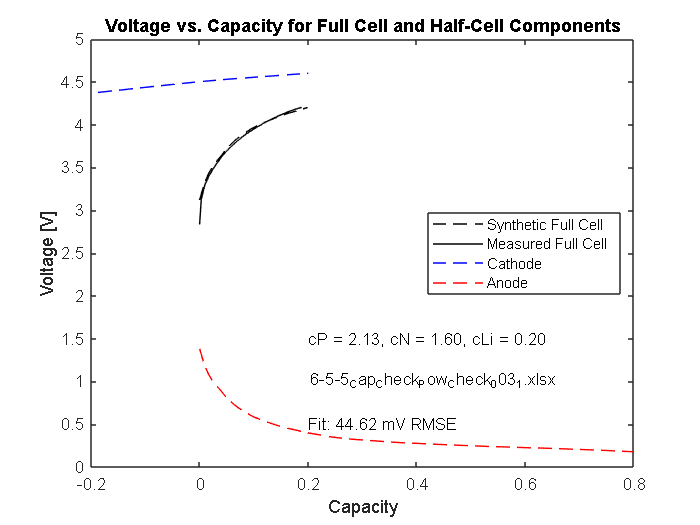

% Create synthetic full cell trace
cP = 2.13;
x0 = 0;
vMin = 2.8;
vMax = 4.2;
chargeDir = "chg";

cLi = 0.2;
cN = 1.6;

[~, ~, ~, y0] = esohFromCompInv(cN, cP, cLi);

[cVecNModel, vVecNModel, cVecPModel, vVecPModel, cVecFullModel, vVecFullModel] = combineHalfCells(thetaVecN, ...
    vThetaVecN, thetaVecP, vThetaVecP, cN, cP, x0, y0, vMin, vMax, chargeDir);

%plotHalfCellModel(cVecNModel, vVecNModel, cVecPModel, vVecPModel, cVecFullModel, vVecFullModel, "-")
%legend(["Synthetic Full Cell", "Cathode", "Anode"])

txt = sprintf("cP = %0.2f, cN = %0.2f, cLi = %0.2f", cP, cN, cLi);

deltaV = sqrt(mean((flip(vThetaVecFull) - vVecFullModel).^2, 'all')).*1000;

plotHalfCellDecomposition(cVecNModel, vVecNModel, cVecPModel, vVecPModel, cVecFullModel, vVecFullModel, cVecFull, vVecFull)
legend(["Synthetic Full Cell", "Measured Full Cell", "Cathode", "Anode"], 'location', 'east')
xlim([-0.2,0.8])
text(0.2,1.5,txt)
text(0.2, 1, fileName)
text(0.2,0.5, sprintf("Fit: %0.2f mV RMSE", deltaV))